## Calculations

This is cleaned up calculations, to be documented, for determining the control system for our quadcopter.

Declare our symbolics

syms x1 x2 x3 phi theta psi v1 v2 v3 omega1 omega2 omega3 
syms u1 u2 u3 u4
syms g m l sigma c1 c2 c3 r1 r2 r3 e1 e2 e3 Ix Iy Iz

Build our system for our $\dot{z}$.

z = [x1; x2; x3; phi; theta; psi; v1; v2; v3; omega1; omega2; omega3;];
u = [u1; u2; u3; u4;];

T_inv=[
        1 sin(phi)*tan(theta) cos(phi)*tan(theta);
        0 cos(phi) -sin(phi);
        0 sin(phi)/cos(theta) cos(phi)/cos(theta)
       ];

R_ce = [
            cos(theta)*cos(psi)         sin(phi)*sin(theta)*cos(psi)-cos(phi)*sin(psi)      sin(phi)*sin(psi)+cos(phi)*sin(theta)*cos(psi);
            cos(theta)*sin(psi)         cos(phi)*cos(psi)+sin(phi)*sin(theta)*sin(psi)      cos(phi)*sin(theta)*sin(psi)-sin(phi)*cos(psi);
            -sin(theta)                 sin(phi)*cos(theta)                                 cos(phi)*cos(theta);
       ];

e1=[1; 0; 0];
e2=[0; 1; 0];
e3=[0; 0; 1];

c1=[1; 0; 0];
c2=[0; 1; 0];
c3=[0; 0; 1];

n=[0; 0; 0];
r=[0; 0; 0];

I=[Ix 0 0;
    0 Iy 0;
    0 0 Iz];

xdot = [v1; v2; v3;];
alphadot = simplify(T_inv * [omega1; omega2; omega3;]);
vdot=simplify(-g*e3+1/m*(R_ce*(u1+u2+u3+u4)*c3+1/m*R_ce*r));
omegadot=simplify(inv(I)*((u2-u4)*l*c1+(u3-u1)*l*c2+(u1-u2+u3-u4)*sigma*c3+n-cross([omega1; omega2; omega3;],I*[omega1; omega2; omega3;])));

zdot = [xdot; alphadot; vdot; omegadot;];

From our calculated $\dot{z}$, find A and B via the Jacobian. We are also assuming that we are near a hover position to linearize the equation - essentially $\phi$, $\theta$, and $\psi$ are 0, and $u_1 +u_2 +u_3 +u_4 =\textrm{mg}$, thus $u_i =\frac{\textrm{mg}}{4}$.

global A B

A = jacobian(zdot, z);
B = jacobian(zdot, u);

phi=0;
theta=0;
psi=0;
v1=0;
v2=0;
v3=0;
omega1=0;
omega2=0;
omega3=0;
u1=m*g/4;
u2=m*g/4;
u3=m*g/4;
u4=m*g/4;

A = subs(A);
B = subs(B);

Now we check for the controllability of our control matrix.

C = [B A*B A^2*B A^3*B A^4*B A^5*B A^6*B A^7*B A^8*B A^9*B A^10*B A^11*B];
rank(C);

We see that the rank of the C matrix is equivalent to our size of z, so we have a fully controllable system.

interceptor = create_quadcopter([0 0 0], [0 0 0], [0 0 0], [0 0 0], 0.5, .2, .08, 'blue', 'green', 'blue');

[a, b] = get_quadcopter_A_and_B(interceptor);

Once we have our A and B, we assign to the quacopter a Q and R for our desired performance.

interceptor.Q = eye(12);
interceptor.R = eye(4);

...and finally, we have MATLAB calculate the resulting K for our given system via the lqr function.

interceptor.K = lqr(a, b, interceptor.Q, interceptor.R);
interceptor.K;

Now that we have our K for our given interceptor model, we can generate a trajectory via solving the ODE for the given system of $\dot{e}$ utilizing our calculated K. Here we will assign our quadcopter a given starting stationary position and end at another stationary position.

interceptor.xyz = [0 0 0];
e0 = [0;0;0;0;0;pi;0;0;0;0;0;0];
tspan = 0:0.1:5;
[t,e] = ode45(@(t,e) (a-b*interceptor.K)*e,tspan,e0);

Now, given our error over time, we can utilize that to blah blah

z_desired = [5; 5; 5; 0; 0; 0; 0; 0; 0; 0; 0; 0;];
states = calculate_trajectory_to_state(interceptor, z_desired, tspan);

## Drawing our quadcopter in motion

Here, we are testing some drawing tools to draw our quadcopter in motion.

figure
hold on

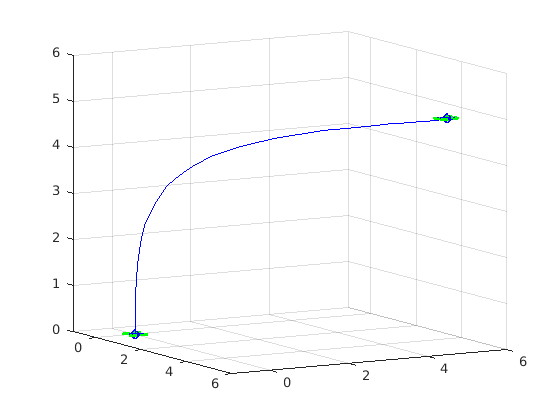

view(60,10)
grid on
xlim([-1, 6])
ylim([-1,6])
zlim([0,6])
hold on;

plot_quadcopter_trajectory(states);
exportgraphics(gcf,'MoveAndHover.png', 'Resolution', 300);
hold off

## Intercepting Another Drone

Now that we have trajectory drawing for a set trajectory, and a quadcopter with a control system, let's see if we can code a system for our interception. We'll need to rework the control logic to swap the desired position of our interceptor drone for the changing position of our target drone. We'll have to also detect where, if at all, the interceptor drone is within a certain magnitude distance of the target drone so as to represent "capture".

To do this, we will generate the trajectory over a set amount of time for each, and then compare the trajectories at each timestamp.

Please see intercept_drone function below.

tspan = 0:0.1:50;
syms t
target_trajectory = @(t) [ 10-t/6; 3+t/6; sin(t)/3+5;];
target_xyz = transpose(target_trajectory(0));
target = create_quadcopter(target_xyz, [0 0 0], [0 0 0], [0 0 0], 0.1, .2, .04, 'red', 'red', 'red');
interceptor = create_quadcopter([0 0 0], [0 0 0], [0 0 0], [0 0 0], 0.5, .2, .08, 'blue', 'blue', 'blue');

% [interceptor_states, target_states, time_intercept] = intercept_drone(interceptor, target, target_trajectory, tspan)
interceptor.Q = eye(12);
interceptor.Q(1,1) = 3.9665;
interceptor.Q(2,2) = 3.9665;
interceptor.Q(3,3) = .25;

interceptor.Q(1,1) = 1.5;
interceptor.Q(2,2) = 1.5;
interceptor.Q(3,3) = 1;


interceptor.Qcaptured = eye(12);
interceptor.Qcaptured(1,1) = 1;
interceptor.Qcaptured(2,2) = 1;
interceptor.Qcaptured(3,3) = 0.01;
global captured captured_at;
captured = false;
captured_at = 10000;
 
[interceptor_states, target_states, time_intercept] = intercept_drone(interceptor, target, target_trajectory, tspan);

f=figure;
hold on;
view(60,10)
grid on
%xlim([-20, 20])
%ylim([-20,20])
zlim([0,10])

plot_quadcopter_trajectory(target_states);
hold on;
plot_quadcopter_trajectory(interceptor_states);
captured_at

captured_at = 5.3236

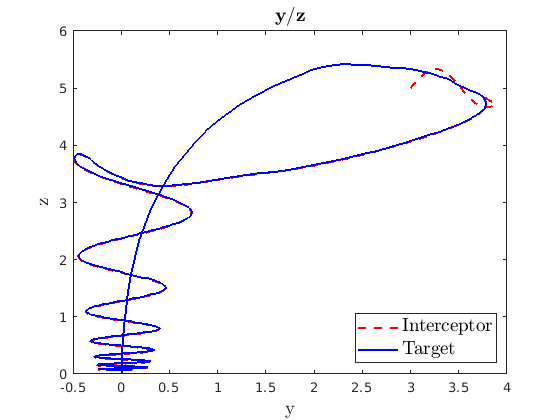

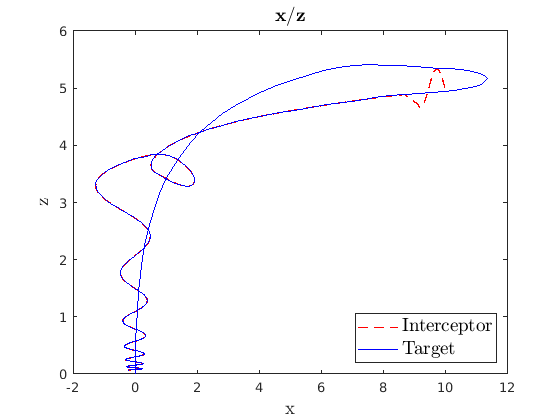

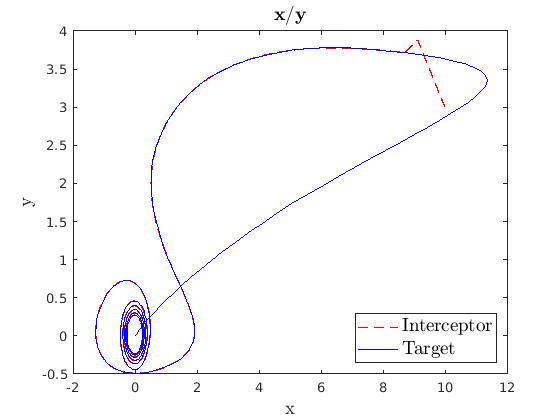

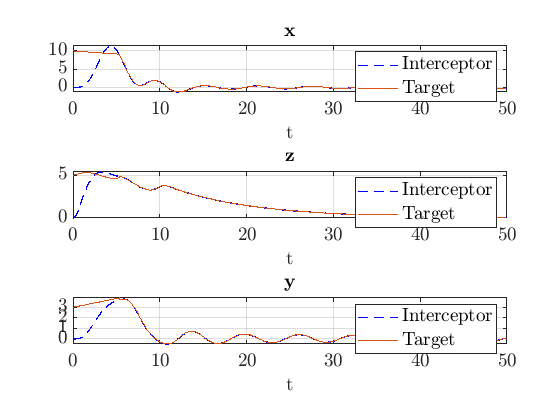

exportgraphics(gcf,'Intercept.png', 'Resolution', 300);

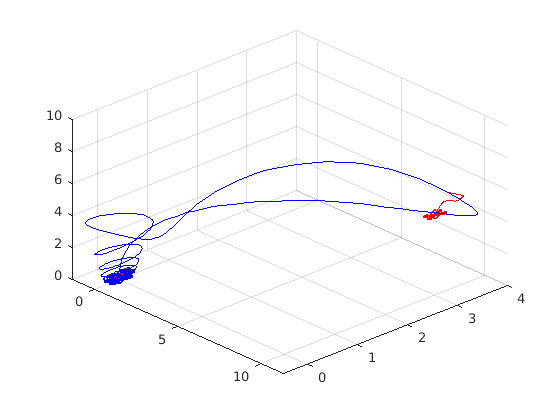

hold off;

## Intercept Functions

These are functions that aid in the process of intercepting and capturing a target drone.

### intercept_drone

intercept_drone accepts a given interceptor drone, a given target drone, the target drone's path, and a given timespan. It will then return the state list for each quadcopter, and a time that they became close enough to be considered "intercepting". Note that if no intercept exists, then the time_intercept result will be -1.

function [interceptor_states, target_states, time_intercept] = intercept_drone(interceptor, target, target_trajectory, tspan)
% function [t, z] = intercept_drone(interceptor, target, target_trajectory, tspan)
    time_intercept = -1;
    interceptor_states = [];
    target_states = [];
    
    interceptor = prepare_quadcopter_for_control_system(interceptor);
    
    z0 = z_from_quadcopter(interceptor);
    
    global captured captured_at;
    %captured = false;
    %captured_at = 10000;
    
    [t,z]=ode45(@(t,z) intercept_control_ode(interceptor, target_trajectory, t, z), tspan, z0);
    
    time_intercept = captured_at;
    
    % Now that we've got our error over a given time, let's apply it to
    % our quadcopter by generating a series of quadcopter states.
    for i = 1:size(z,1)
        z_desired = target_trajectory(tspan(i));
        zi = transpose(z(i,:));
        
        if tspan(i) > captured_at
            target.xyz = transpose(zi(1:3));
        else
            target.xyz = transpose(z_desired(1:3));
        end
        
        target_states = [target_states target];
        
        quad_new = quadcopter_to_z(interceptor, zi);
        interceptor_states = [interceptor_states quad_new];
    end
    plotDiagnostics(t,interceptor_states, target_states)
end

### intercept_control_ode

We need to do a bunch of variable reassignment during the intercept ODE. As a result, it's easier to just handle it as a function rather than an anonymous function.

function zdot = intercept_control_ode(interceptor, target_trajectory, t, z)
    global captured captured_at distance_between_quads;
    home = zeros(12, 1);
    capture_distance = interceptor.arm_length * 4;
    capture_distance = .3;
    chase_zone_radius = 20;
    target_state = [target_trajectory(t); zeros(9,1)];
    
    % Is the target within the capture zone? If so, our desired state is
    % our target state. Otherwise it's 0,0. Alternatively, if our
    % quadcopter is within capture distance, the desired xyz is back home.
    distance_between_quads = distance_formula(target_state(1:3), z(1:3));
    chase = within_chase_zone(target_state(1:3), chase_zone_radius);
    if chase && ~captured && distance_between_quads > capture_distance
        desired_state = target_state;
    elseif chase && distance_between_quads <= capture_distance
        if ~captured
            captured = true;
            captured_at = t; 
        end
        desired_state = home;
    else
        desired_state = home;
    end
    
    error = desired_state-z;
    
    distance_between_home_and_interceptor = distance_formula(home(1:3), z(1:3));
    
    finished = false;
    
    % Finally we calculate the u, and then from there calculate our zdot!
    if ~captured
       n=[0; 0; 0;];
       r=[0; 0; 0;];
       K = interceptor.K;
    elseif captured && distance_between_home_and_interceptor < interceptor.arm_length
       finished = true;
       K = interceptor.K;
       r=[0;0;0;];
       n=[0;0;0;];
    else
       g = 9.81;
       n=[sin(t)/10; cos(t)/10; sin(t)/10];
       r=[0; 0; 0;];
       K = interceptor.Kcaptured;
       interceptor.mass = interceptor.mass + 0.1;
    end
    
    u = K*error + ((interceptor.mass*9.81)/4);
    u = max(min(u, 3), 0);
    zdot = zdot_from_u(interceptor, z, u, r, n); 
    
    if finished
        zdot = zeros(12,1);
    end
end

## State Functions

### zdot_from_u

zdot_from_u function, given a quadcopter, a vector u (input to system), and a force of an known magnitude against the quadcopter, generate the resulting zdot (change) of the state.

function zdot = zdot_from_u(quadcopter, z, u, r, n) 
%     z(3) = max(z(3), 0);
    phi = z(4);
    theta = z(5);
    psi = z(6);
    
    sigma = 0.01;
    
    l = quadcopter.arm_length;
    
    T_inv=[
                1 sin(phi)*tan(theta) cos(phi)*tan(theta);
                0 cos(phi) -sin(phi);
                0 sin(phi)/cos(theta) cos(phi)/cos(theta)
           ];
    
    R_ce = [
                cos(theta)*cos(psi)         sin(phi)*sin(theta)*cos(psi)-cos(phi)*sin(psi)      sin(phi)*sin(psi)+cos(phi)*sin(theta)*cos(psi);
                cos(theta)*sin(psi)         cos(phi)*cos(psi)+sin(phi)*sin(theta)*sin(psi)      cos(phi)*sin(theta)*sin(psi)-sin(phi)*cos(psi);
                -sin(theta)                 sin(phi)*cos(theta)                                 cos(phi)*cos(theta);
           ];
    
    e1=[1; 0; 0];
    e2=[0; 1; 0];
    e3=[0; 0; 1];
    
    c1=[1; 0; 0];
    c2=[0; 1; 0];
    c3=[0; 0; 1];
    
    I = [
            1.24  0     0;
            0     1.24  0;
            0     0     2.48;
        ];
    
    % rt = torque vector induced by rotor thrusts
    %       g,  l,  m, I11, I22, I33, mu, sigma
    p = [
        9.81; quadcopter.arm_length; quadcopter.mass; 1.24; 1.24; 2.48; 3.0; 0.01;
    ];
    R = R_ce;
    rt = [                   ( u(2) - u(4) )*p(2); 
                             ( u(3) - u(1) )*p(2); 
               ( u(1) - u(2) + u(3) - u(4) )*p(8)];
    
    
    % Computing time derivative of the state vector
    dz = zeros(12,1);
    dz(1:3,1) = z(7:9,1);
    
    dz(4:6,1) = [ z(10) + z(12)*cos(z(4))*tan(z(5)) + z(11)*sin(z(4))*tan(z(5));
                                              z(11)*cos(z(4)) - z(12)*sin(z(4));
                                  (z(12)*cos(z(4)) + z(11)*sin(z(4)))/cos(z(5))];
                          
    dz(7:9,1) = R*([0; 0; sum(u)] + r)/p(3) - [0; 0; p(1)];
    
    dz(10:12,1) = I\( rt + n - cross( z(10:12,1) , I * z(10:12,1) ) );
    
    xdot = [z(7); z(8); z(9);];
    alphadot = T_inv * [z(10); z(11); z(12);];
    vdot= -9.81*e3+1/quadcopter.mass*(R_ce*(sum(u))*c3+1/quadcopter.mass*R_ce*r);
    omegadot=inv(I)*((u(2)-u(4))*l*c1+(u(3)-u(1))*l*c2+(u(1)-u(2)+u(3)-u(4))*sigma*c3+n-cross([z(10); z(11); z(12);],I*[z(10); z(11); z(12);]));

    zdot = [xdot; alphadot; vdot; omegadot;];
end

### z_from_quadcopter

z_from_quadcopter takes a quadcopter and returns its current z state

function z = z_from_quadcopter(quadcopter)
    z = [
        transpose(quadcopter.xyz);
        transpose(quadcopter.rotation);
        transpose(quadcopter.velocity);
        transpose(quadcopter.omega);
    ];
end

### quadcopter_to_z

quadcopter_to_z takes a quadcopter and a z and returns that adjusted quadcopter.

function quadcopter = quadcopter_to_z(quadcopter, z)
    quadcopter.xyz = transpose(z(1:3));
    quadcopter.rotation = transpose(z(4:6));
    quadcopter.velocity = transpose(z(7:9));
    quadcopter.omega = transpose(z(10:12));
end

## Control Functions

### calculate_trajectory_to_state

calculate_trajectory_to_state takes a given quadcopter, a desired state z, and a timespan. It will then utilize its control system (or generate one if it has not done so already), and utilize that to create a trajectory consisting of a series of quadcopter states. It does this by solving the ODE for our system $\dot{e}$.

function quadcopter_states = calculate_trajectory_to_state(quadcopter, z, tspan)
    quadcopter_states = [];
    
    quadcopter = prepare_quadcopter_for_control_system(quadcopter);
    
    e_xyz = z(1:3) - transpose(quadcopter.xyz);
    e_rotation = z(4:6) - transpose(quadcopter.rotation);
    e_v = z(7:9) - transpose(quadcopter.velocity);
    e_omega = z(10:12) - transpose(quadcopter.omega);
    e0 = [e_xyz; e_rotation; e_v; e_omega;];
    
    [t,e]=ode45(@(t,e) (quadcopter.A-quadcopter.B*quadcopter.K)*e,tspan,e0);
    
    % Now that we've got our error over a given time, let's apply it to
    % our quadcopter by generating a series of quadcopter states.
    for i = 1:length(e)
%         error = e0 - transpose(e(i,:));
        error = transpose(e(i,:));
        zi = z - error;
        quad_new = quadcopter;
        quad_new.xyz = transpose(zi(1:3));
        quad_new.rotation = transpose(zi(4:6));
        quad_new.velocity = transpose(zi(7:9));
        quad_new.omega = transpose(zi(10:12));
        quadcopter_states = [quadcopter_states quad_new];
    end
end

### prepare_quadcopter_for_control_system

prepare_quadcopter_for_control_system accepts a quadcopter object and returns it. If the A, B, Q, R, or K were not already set on this quadcopter, it will generate defaults for all of them and assign it, returning a quadcopter with the settings configured.

function quadcopter = prepare_quadcopter_for_control_system(quadcopter)
    if ~isfield(quadcopter, 'A') | ~isfield(quadcopter, 'B')
        [a, b] = get_quadcopter_A_and_B(quadcopter);
        quadcopter.A = a;
        quadcopter.B = b;
    end
    
    if ~isfield(quadcopter, 'Acaptured') | ~isfield(quadcopter, 'Bcaptured')
        quadcopter_copy = quadcopter;
        quadcopter_copy.mass = quadcopter.mass + 0.1;
        [a, b] = get_quadcopter_A_and_B(quadcopter_copy);
        quadcopter.Acaptured = a;
        quadcopter.Bcaptured = b;
    end
    
    if ~isfield(quadcopter, 'Q')
        quadcopter.Q = eye(12);
    end
    
    if ~isfield(quadcopter, 'R')
        quadcopter.R = eye(4);
    end
    
    if ~isfield(quadcopter, 'K')
        quadcopter.K = lqr(quadcopter.A, quadcopter.B, quadcopter.Q, quadcopter.R);
    end
    
    if ~isfield(quadcopter, 'Qcaptured')
        quadcopter.Qcaptured = eye(12);
    end
    
    if ~isfield(quadcopter, 'Kcaptured')
        quadcopter.Kcaptured = lqr(quadcopter.Acaptured, ...
            quadcopter.Bcaptured, ...
            quadcopter.Qcaptured, ...
            quadcopter.R);
    end
end

### get_quadcopter_A_and_B

get_quadcopter_A_and_B takes a given quadcopter object, and returns the A and B numerical matrix for its control. It reaches for the global syms generated A and B for now.

function [a, b] = get_quadcopter_A_and_B(quadcopter)
    global A B
    syms m l Ix Iy Iz g
    a = subs(A, [m l Ix Iy Iz "sigma" g], [...
        quadcopter.mass quadcopter.arm_length ...
        1.24 1.24 2.48 0.01 9.81]);
    b = subs(B, [m l Ix Iy Iz "sigma" g], [...
        quadcopter.mass quadcopter.arm_length ...
        1.24 1.24 2.48 0.01 9.81]);
    a = double(a);
    b = double(b);
end

### trajectory_to_quadcopter_states

trajectory_to_quadcopter_states accepts a given 

function quadcopter_states = trajectory_to_quadcopter_states(quadcopter, xyz_trajectory)
    quadcopter_states = [];
    for t = 1:length(xyz_trajectory)
        tmp_quad = quadcopter;
        tmp_quad.xyz = transpose(xyz_trajectory(:,t));
        quadcopter_states = [quadcopter_states tmp_quad];
    end
end

## Quadcopter Functions

### create_quadcopter

create_quadcopter creates a quadcopter struct object for tracking stats abouts the quadcopter for easily handling. It also tracks the current xyz

function quadcopter = create_quadcopter(xyz, rotation, velocity, omega, mass, arm_length, prop_size, arms_color, props_color, trajectory_color)
    quadcopter = struct(...
        "mass", mass, "arm_length", arm_length, "prop_size", prop_size, ...
        "arms_color", arms_color, "props_color", props_color, ...
        "trajectory_color", trajectory_color, "u_limit", 1000, ...
        "xyz", xyz, "rotation", rotation, "velocity", velocity, "omega", omega);
end

### quadcopter_rotation

quadocopter_rotation will, given a quadcopter, return the roll pitch yaw rotation matrix for the current orientation.

function R = quadcopter_rotation(quadcopter)
    phi = quadcopter.rotation(1);
    theta = quadcopter.rotation(2);
    psi = quadcopter.rotation(3);
    R=[cos(theta)*cos(psi) sin(phi)*sin(theta)*cos(psi)-cos(phi)*sin(psi) sin(phi)*sin(psi)+cos(phi)*sin(theta)*cos(psi);
    cos(theta)*sin(psi) cos(phi)*cos(psi)+sin(phi)*sin(theta)*sin(psi) cos(phi)*sin(theta)*sin(psi)-sin(phi)*cos(psi);
    -sin(theta) sin(phi)*cos(theta) cos(phi)*cos(theta)];
end

### update_quadcopter

update_quadcopter takes a quadcopter and a $\dot{z}$ and returns a quadcopter with updated values

function quadcopter = update_quadcopter(quadcopter, zdot)
    delta_xyz = [zdot(1); zdot(2); zdot(3);];
    delta_rotation = [zdot(4); zdot(5); zdot(6);],
    quadcopter = move_quadcopter(quadcopter, delta_xyz, delta_rotation);
end

### move_quadcopter

move_quadcopter takes a quadcopter and a given delta xyz and delta rotation. These move the quadcopter the given delta from its current position/orientation to its resulting new one. Because MATLAB is pass by value, it returns a new quadcopter struct.

function quadcopter = move_quadcopter(quadcopter, delta_xyz, delta_rotation)
    quadcopter.xyz = quadcopter.xyz + delta_xyz;
    quadcopter.rotation = quadcopter.rotation + delta_rotation;
end

### distance_formula

function distance = distance_formula(xyz1, xyz2)
    distance = sqrt(sum((xyz1-xyz2).^2));
end

### within_chase_zone

function within = within_chase_zone(xyz, radius)
    within = distance_formula(xyz, [0; 0; 0;]) <= radius;
end

### function distance

## Drawing Functions

### plot_quadcopter

plot_quadcopter will take a given a quadcopter struct object. From this object it will ascertain the XYZ center origin of a drone (center of mass), and given roll, pitch, yaw orientation (in radians). It assumes that a figure is already active to be drawing in.

It will return the resutling graphics handles for optional cleanup in case of animation. Color options that can be passed in are optional, in the event of desired variability in copter design.

function handles = plot_quadcopter(quadcopter)
    handles = [];

    center = quadcopter.xyz;
    r = quadcopter.prop_size;
    rotate = quadcopter_rotation(quadcopter);
    l = quadcopter.arm_length;
    
    z = [0;0;1];
    
    norm = transpose(r*z);
    
    %the base quad setup at zero
    LF0 = [l*cos(pi/4);l*sin(pi/4);0];
    LR0 = [l*cos(3*pi/4);l*sin(3*pi/4);0];
    RR0 = [l*cos(5*pi/4);l*sin(5*pi/4);0];
    RF0 = [l*cos(7*pi/4);l*sin(7*pi/4);0];
    
   %Quad rotated through R matrix
    LF = [center; [center+transpose(rotate*LF0)]];
    LR = [center; [center+transpose(rotate*LR0)]];
    RR = [center; [center+transpose(rotate*RR0)]];
    RF = [center; [center+transpose(rotate*RF0)]];
    
    %plotting
    handles = [plot3(center(1), center(2), center(3),"-bo", "LineWidth", 2, 'Color', quadcopter.arms_color)];
    handles = [handles; plot3(LF(:,1), LF(:,2),LF(:,3),"-", "LineWidth", 2, 'Color', quadcopter.arms_color)];
    handles = [handles; plot_circle_3d(LF(2,:), norm,r, quadcopter.props_color)];
    handles = [handles; plot3(LR(:,1), LR(:,2),LR(:,3),"-", "LineWidth", 2, 'Color', quadcopter.arms_color)];
    handles = [handles; plot_circle_3d(LR(2,:),norm,r, quadcopter.props_color)];
    handles = [handles; plot3(RR(:,1), RR(:,2),RR(:,3),"-", "LineWidth", 2, 'Color', quadcopter.arms_color)];
    handles = [handles; plot_circle_3d(RR(2,:), norm,r, quadcopter.props_color)];
    handles = [handles; plot3(RF(:,1), RF(:,2),RF(:,3),"-", "LineWidth", 2, 'Color', quadcopter.arms_color)];
    handles = [handles; plot_circle_3d(RF(2,:), norm,r, quadcopter.props_color)];

end

### plot_circle_3d

plot_circle_3d takes a circle center, its normal vector, and a radius. It then draws the resulting circle in 3d space at the correct orientation.

function h=plot_circle_3d(center,normal,radius, color)
    theta=0:0.01:2*pi;
    v=null(normal);
    points=repmat(center',1,size(theta,2))+radius*(v(:,1)*cos(theta)+v(:,2)*sin(theta));
    h=plot3(points(1,:),points(2,:),points(3,:),'-',  "LineWidth", 2, 'Color', color);
end

### plot_quadcopter_trajectory

plot_quadcopter_trajectory takes a an array of quadcopter structs, each representing a state of the quadcopter at a given point in time. From this, it will generate a list of XYZ center points denoting where the quadcopter is, a list of roll pitch yaw rotations. It plots the points of the trajectory as a dotted line of the quadcopter's specified trajectory color. It will plot the quadcopter at the beginning and end of the path.

function handles = plot_quadcopter_trajectory(quadcopter_states)
    % First plot the trajectory
    handles = [];
    xyzs = zeros(3, length(quadcopter_states));
    for i = 1:length(quadcopter_states)
        xyzs(:, i) = quadcopter_states(i).xyz;
    end
%     plot3(xyzs(1,:), xyzs(2,:), xyzs(3,:), "-o", "MarkerSize", 6, "MarkerEdgeColor", quadcopter_states(1).trajectory_color);
    plot3(xyzs(1,:), xyzs(2,:), xyzs(3,:), "-", "Color", quadcopter_states(1).trajectory_color);
    
    % Now plot the start and finish
    plot_quadcopter(quadcopter_states(1));
    plot_quadcopter(quadcopter_states(length(quadcopter_states)));
end


### plot2d trajectories

function plotDiagnostics=plotDiagnostics(t,interceptor_states, target_states)
for i=1:3
    ax(i) = subplot(3,1,i,'NextPlot','Add','Box','on','XGrid','on','YGrid','on',...
                'Xlim',[t(1), t(end)],...
                'TickLabelInterpreter','LaTeX','FontSize',14);
    xlabel('t','Interpreter','LaTeX','FontSize',14);        
end

%xyzs for the interceptor
i_xyzs = zeros(3, length(interceptor_states));
    for i = 1:length(interceptor_states)
        i_xyzs(:, i) = interceptor_states(i).xyz;
    end
%xyzs for the target
t_xyzs = zeros(3, length(target_states));
   for i = 1:length(target_states)
        t_xyzs(:, i) = target_states(i).xyz;
    end

plot(ax(1), t,i_xyzs(1,:), '--b',t,t_xyzs(1,:), 'LineWidth', 1.);
legend(ax(1), {'Interceptor', 'Target'},... 
    'Interpreter', 'LaTeX', 'FontSize', 14);
title(ax(1), '${\bf x}$','Interpreter','LaTeX','FontSize',14);
xlabel(ax(1), 't','Interpreter','LaTeX','FontSize',14);

plot(ax(3),  t,i_xyzs(2,:),'--b',t,t_xyzs(2,:), 'LineWidth', 1.);
legend(ax(3), {'Interceptor', 'Target'},... 
    'Interpreter', 'LaTeX', 'FontSize', 14);
title(ax(3), '${\bf y}$','Interpreter','LaTeX','FontSize',14);

plot(ax(2),  t,i_xyzs(3,:), '--b',t,t_xyzs(3,:), 'LineWidth', 1.);
legend(ax(2), {'Interceptor', 'Target'},... 
    'Interpreter', 'LaTeX', 'FontSize', 14);
title(ax(2),'${\bf z}$','Interpreter','LaTeX','FontSize',14);

%Plot the xy of each

f1=figure;
plot( t_xyzs(1,:),t_xyzs(2,:),'--r', i_xyzs(1,:),i_xyzs(2,:), '-b','LineWidth',1);
legend({'Interceptor', 'Target'},... 
    'Interpreter', 'LaTeX', 'FontSize', 14);
legend('Location','southeast')
title( '${\bf x/y}$','Interpreter','LaTeX','FontSize',14);
xlabel( 'x','Interpreter','LaTeX','FontSize',14);
ylabel('y','Interpreter','LaTeX','FontSize',14);

f2=figure;
plot( t_xyzs(1,:),t_xyzs(3,:),'--r', i_xyzs(1,:),i_xyzs(3,:), '-b','LineWidth',1);
legend( {'Interceptor', 'Target'},... 
    'Interpreter', 'LaTeX', 'FontSize', 14);
legend('Location','southeast')
title( '${\bf x/z}$','Interpreter','LaTeX','FontSize',14);
ylabel( 'z','Interpreter','LaTeX','FontSize',14);
xlabel( 'x','Interpreter','LaTeX','FontSize',14);

f3=figure;
plot( t_xyzs(2,:),t_xyzs(3,:),'--r', i_xyzs(2,:),i_xyzs(3,:), '-b','LineWidth',1.5);
legend( {'Interceptor', 'Target'},... 
    'Interpreter', 'LaTeX', 'FontSize', 14);
legend('Location','southeast')
title('${\bf y/z}$','Interpreter','LaTeX','FontSize',14);
ylabel( 'z','Interpreter','LaTeX','FontSize',14);
xlabel( 'y','Interpreter','LaTeX','FontSize',14);

end